duration = 2;       % Duration in seconds
fs = 1e3;  % Sampling rate in Hz

t = 0:1/fs:duration;

trend = sin(2*pi*1/2*t);
x1 = sin(2*pi*120*t).*(t>0.1 & t<1.5);
x2 = sin(2*pi*70*t).*(t>1.2);

rng default
wgnNoise = 0.4*randn(size(t));

x = trend+x1+x2+wgnNoise;
% x = trend+x1+x2;

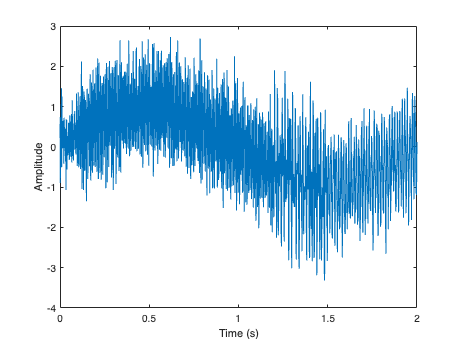

plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');

sound(x,fs,16);

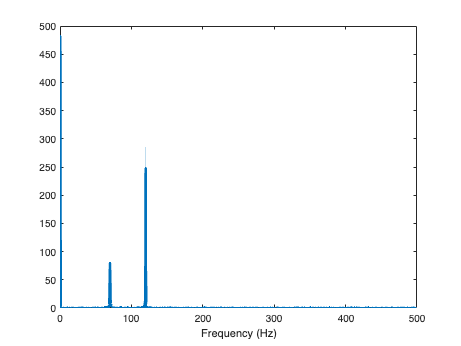

% power spectrum
dt = 1/fs;
n = length(t);
xhat = fft(x, n);
PSD = xhat.*conj(xhat)/n; % power spectrum (power per freq)
freq = 1/(dt*n)*(0:n); % create the x-axis of freqs in Hz
L = 1:floor(n/2); % only plot the first half of the freqs

figure
plot(freq(L),PSD(L),'LineWidth',2.5)
xlabel('Frequency (Hz)')

gammaFiltBank = gammatoneFilterBank('SampleRate',fs, ...
                                    'NumFilters',32, ...
                                    'FrequencyRange',[0,500]);
audioOut = gammaFiltBank(x);